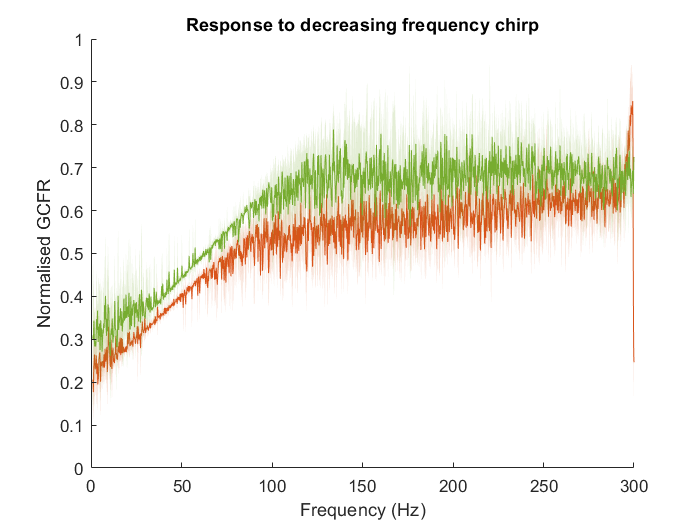

for i=22:23
    fs = chirp_meta_struct(i).moth.fs;
    max_frq = chirp_meta_struct(i).moth.max_chirp_frq;
    ON_dur = chirp_meta_struct(i).moth.ON_dur;
    OFF_dur = chirp_meta_struct(i).moth.OFF_dur;
    gcfr = chirp_meta_struct(i).moth.norm_gcfr(:,OFF_dur*fs:(OFF_dur+ON_dur)*fs);
    f = linspace(1,max_frq,length(gcfr));
    start_stim = OFF_dur*fs;
    stop_stim  = (ON_dur+OFF_dur)*fs;
    
    
    
    if chirp_meta_struct(i).moth.stim_name == "dec_frq_chirp"
%         continue;
        figure;
        [lineOut, ~] = stdshade(gcfr,0.2,[0.8500 0.3250 0.0980],fliplr(f));
        lineOut.LineWidth  = 0.01;
        ax = gca;
%         ax.YAxis.Visible = "off";
        ax.XTickLabel = fliplr(ax.XTickLabel);
%         ylabel 'Normalised GCFR';
        xlabel 'Frequency (Hz)';
        box off;
        title ('Response to decreasing frequency chirp');
        
    elseif chirp_meta_struct(i).moth.stim_name == "frq_chirp"
%         figure;
        hold on;
        [lineOut, ~] = stdshade(gcfr,0.2,[0.4660 0.6740 0.1880],f);
%         [lineOut, ~] = stdshade(gcfr,0.2,'k',f);
        lineOut.LineWidth = 0.01;
        ylim ([0 1]);
        ylabel 'Normalised GCFR';
        ax=gca;
%         ax.YAxis.Visible = "off";
        xlabel 'Frequency (Hz)';
%         title ('Response to increasing frequency chirp');
        box off;

%         [I_spike_phase, II_spike_phase, III_spike_phase, I_spike_freq, II_spike_freq, III_spike_freq] = spike_phase(chirp_meta_struct(i).moth.antennal_movement(1,:), chirp_meta_struct(i).moth.raster(1,:), fs, start_stim, stop_stim, chirp_meta_struct(i).moth.stim_type,  f);
%         figure(); scatter(I_spike_freq,I_spike_phase,100, '.k'); hold on;
%         yticks(0:pi/2:2*pi);
%         yticklabels({'0','1/2 \pi', '\pi','3/2 \pi', '2\pi'});
%         scatter(II_spike_freq,II_spike_phase, 100,  'b.');
%         scatter(III_spike_freq,III_spike_phase, 100, 'r.')
%         ylabel('Spike phase (rad)');
%         xlabel('Stimulus frequency (Hz)');
%         box off;
%         legend('I spike','II spike', 'III spike', 'Location', 'best');
    end
end

            %             figure(); scatter(I_spike_freq,I_spike_phase,100, '.k'); hold on;
            %             yticks(0:pi/2:2*pi);
            %             yticklabels({'0','1/2 \pi', '\pi','3/2 \pi', '2\pi'});
            %             scatter(II_spike_freq,II_spike_phase, 100,  'b.');
            %             scatter(III_spike_freq,III_spike_phase, 100, 'r.')
            %             ylabel('Spike phase (rad)');
            %             xlabel('Stimulus frequency (Hz)');
            %             box off;
            %             legend('I spike','II spike', 'III spike', 'Location', 'best');